[x, fs] = audioread('../whisper.wav');

% Convert stereo to mono if needed
if size(x, 2) > 1
    x = x(:,1);
end

% Normalize amplitude for plotting and comparing signals consistently
x = x / max(abs(x));

% Time axis
t = (0:length(x)-1)/fs;

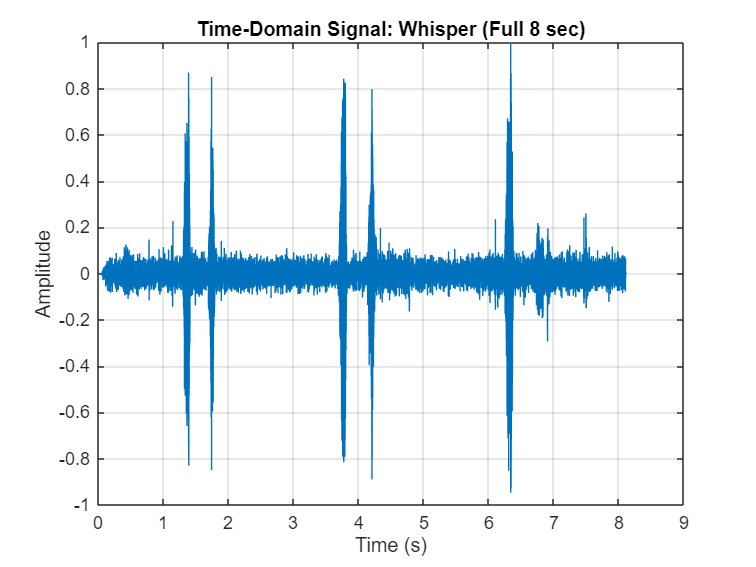

figure;
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Signal: Whisper (Full 8 sec)');
grid on;

addpath('../1.2');

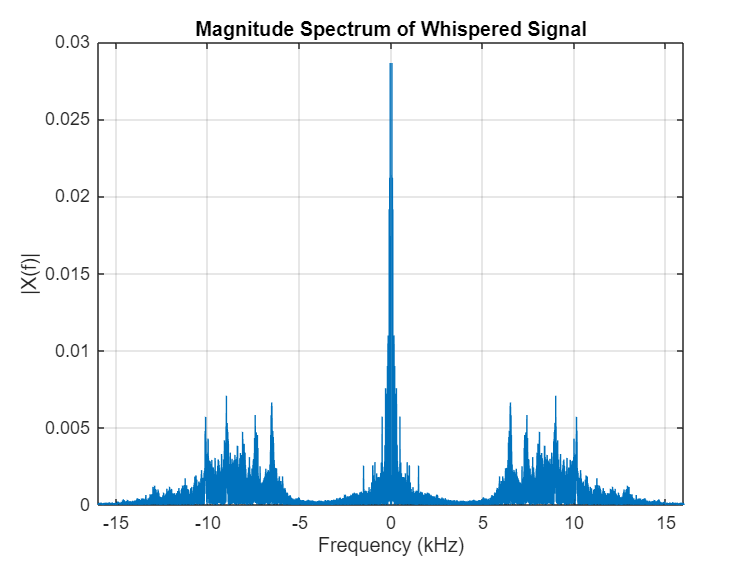

T = t(end);  % total duration in seconds
[f, xf, W] = ftr(t, x, T, 'fft'); % use the fourier transform function we implemented in 1.2 with fft enabled

% Plot the spectrum (magnitude only)
figure;
plot(f/1000, abs(xf));  % Convert frequency to kHz by dividing by 1000
xlabel('Frequency (kHz)');
ylabel('|X(f)|');
title('Magnitude Spectrum of Whispered Signal');
xlim([-16, 16]);  % xlim to kHz range
grid on;